Experiment 1

clear
load("experiment_1.mat")

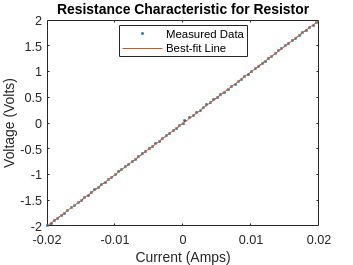

epsil=5e-4;

figure();
plot(I_in, V_in, ".",'DisplayName', 'Measured Data');
hold on
xlabel('Current (Amps)');
ylabel('Voltage (Volts)');

[f1, l1, m1, b1, n1] = linefit(I_in, V_in,epsil);
fitline1 = m1 * I_in + b1;

plot(I_in, fitline1,'DisplayName', 'Best-fit Line');
legend('Measured Data', 'Best-fit Line','Location', 'Best');
xlim([-0.02 0.02])
title("Resistance Characteristic for Resistor")
hold off


resistance = m1; % gradient
fprintf('Calculated Resistance: %.2f Ohms\n', resistance);

Calculated Resistance: 99.88 Ohms


Experiment 2

clear
load("Experiment 2 - WorkSpace.mat")

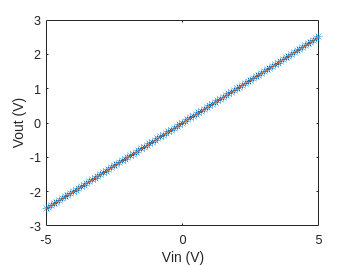

epsil=5e-4;

figure()
plot(Vin,Vout,"*",'DisplayName', 'Measured Data')
hold on
xlabel("Vin (V)")
ylabel("Vout (V)")

[f2, l2, m2, b2, n2] = linefit(Vin, Vout, epsil);
fitline2 = m2 * Vin + b2;
plot(Vin,fitline2, 'DisplayName', 'Best-fit Line');
hold off


ratio = m2; % gradient
fprintf('Calculated Divider Ratio: %.2f\n', ratio);

Calculated Divider Ratio: 0.50


Experiment 3

clear
load("Experiment 3 - WorkSpace.mat")

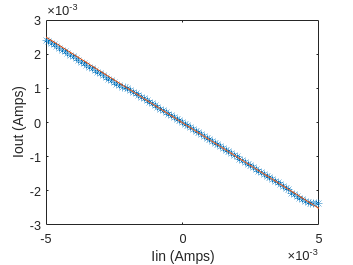

epsil=5e-4;

figure()
plot(Iin,Iout,"*",'DisplayName', 'Measured Data')
hold on
xlabel("Iin (Amps)")
ylabel("Iout (Amps)")

[f3, l3, m3, b3, n3] = linefit(Iin, Iout, epsil);
fitline3 = m3 * Iin + b3;
plot(Iin,fitline3, 'DisplayName', 'Best-fit Line');
hold off


ratio = m3; % gradient
fprintf('Calculated Divider Ratio: %.2f\n', ratio);

Calculated Divider Ratio: -0.50


Experiment 4

clear
load("Experiment 4 - I_out_3_3v.mat")

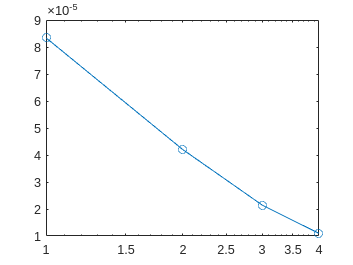

epsil=5e-4;

% would it be semilogx or y that we want for these? 
%semilogy(I_out_3_3v*-1,'-o')

%hold on
%semilogx(I_out_1v*-1,'-o')

%will fit curves once we know that our plotted data is correct